# HW 11 - Ch 14 - Linear Regression

## Prob 1

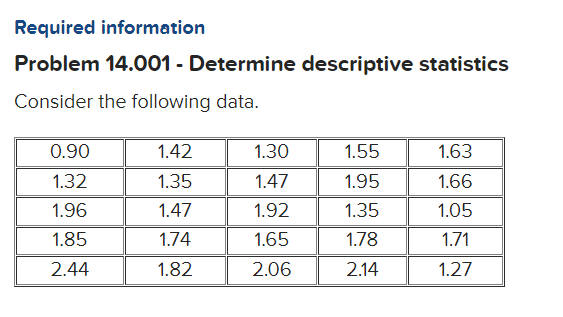

Determine the mean, median, mode, and range for the given data.

% A = [0.90 1.42 1.30 1.55 1.63; 
%      1.32 1.35 1.47 1.95 1.66; 
%      1.96 1.47 1.92 1.35 1.05; 
%      1.85 1.74 1.65 1.78 1.71; 
%      2.44 1.82 2.06 2.14 1.27] % suboptimal - should just be row

A = [0.90 1.42 1.30 1.55 1.63...  
     1.32 1.35 1.47 1.95 1.66... 
     1.96 1.47 1.92 1.35 1.05... 
     1.85 1.74 1.65 1.78 1.71... 
     2.44 1.82 2.06 2.14 1.27];

avg = mean(A)

avg = 1.6304

med = median(A)

med = 1.6500

% [M,F] = mode(A) % FAILS: only designed for having 1 mode - use hist instead
ran = range(A)

ran = 1.5400


s = size(A)

s =      1    25


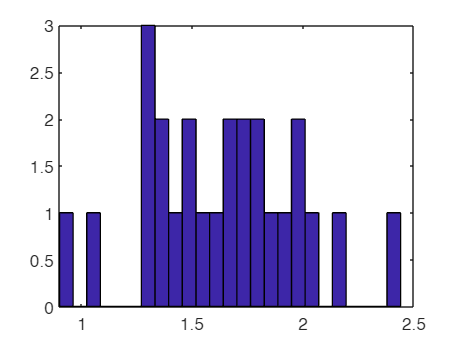

%help mode
hist(A, s(2))

help hist % apparently outdated

 hist  Histogram.
    hist is not recommended. Use HISTOGRAM or HISTCOUNTS instead.
  
    N = hist(Y) bins the elements of Y into 10 equally spaced containers
    and returns the number of elements in each container.  If Y is a
    matrix, hist works down the columns.
 
    N = hist(C) returns the category counts for the categorical array C.
    For a categorical matrix, hist works down the columns of Y and returns
    a matrix of counts with one column for each column of Y and one row for
    each category.
 
    N = hist(Y,M), where M is a scalar, uses M bins.
 
    N = hist(Y,X), where X is a vector, returns the distribution of Y among
    bins with centers specified by X. The first bin includes data between
    -inf and the first center and the last bin includes data between the
    last bin and inf. Note: Use HISTC if it is more natural to specif

help histcounts

 histcounts - Histogram bin counts
    This MATLAB function partitions the X values into bins and returns the
    bin counts and the bin edges.

    Syntax
      [N,edges] = histcounts(X)
      [N,edges] = histcounts(X,nbins)
      [N,edges] = histcounts(X,edges)
      [N,edges,bin] = histcounts(___)

      N = histcounts(C)
      N = histcounts(C,Categories)
      [N,Categories] = histcounts(___)

      [___] = histcounts(___,Name,Value)

    Input Arguments
      X - Data to distribute among bins
        vector | matrix | multidimensional array
      C - Categorical data
        categorical array
      


[N,edges] = histcounts(A, s(2))

N =      1     0     1     0     0     1     2     2     1     2     1     1     2     2     2     1     2     1     1     0     1     0     0     0     1


edges =     0.9000    0.9620    1.0240    1.0860    1.1480    1.2100    1.2720    1.3340    1.3960    1.4580    1.5200    1.5820    1.6440    1.7060    1.7680    1.8300    1.8920    1.9540    2.0160    2.0780    2.1400    2.2020    2.2640    2.3260    2.3880    2.4500


Std way

% Mode (use the script from the previous answer for multi-modal data)
[unique_vals, ~, idx] = unique(A);
counts = accumarray(idx, 1);
modes = unique_vals(counts == max(counts))

modes =     1.3500    1.4700


## Prob 2

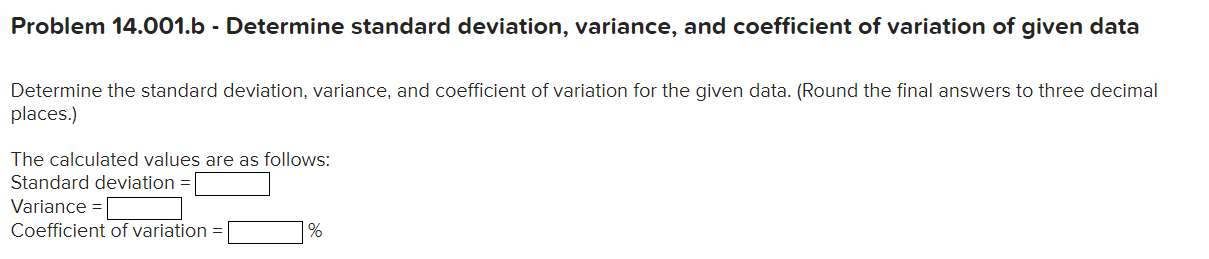

help std

 std Standard deviation.
    For vectors, Y = std(X) returns the standard deviation.  For matrices,
    Y is a row vector containing the standard deviation of each column.  For
    N-D arrays, std operates along the first non-singleton dimension of X.
 
    std normalizes Y by N-1 if N>1, where N is the sample size.  This is
    the sqrt of an unbiased estimator of the variance of the population
    from which X is drawn, as long as X consists of independent,
    identically distributed samples. For N=1, Y is normalized by N.
 
    Y = std(X,1) normalizes by N and produces the square root of the second
    moment of the sample about its mean.  std(X,0) is the same as std(X).
 
    Y = std(X,W) computes the standard deviation using the weight vector W.
    W typically contains either counts or inverse variances.  The length of
    W must equal the lengt

stddev = std(A)

stddev = 0.3527

v = var(A)

v = 0.1244

cv = stddev/avg*100

cv = 21.6333

## Prob 3

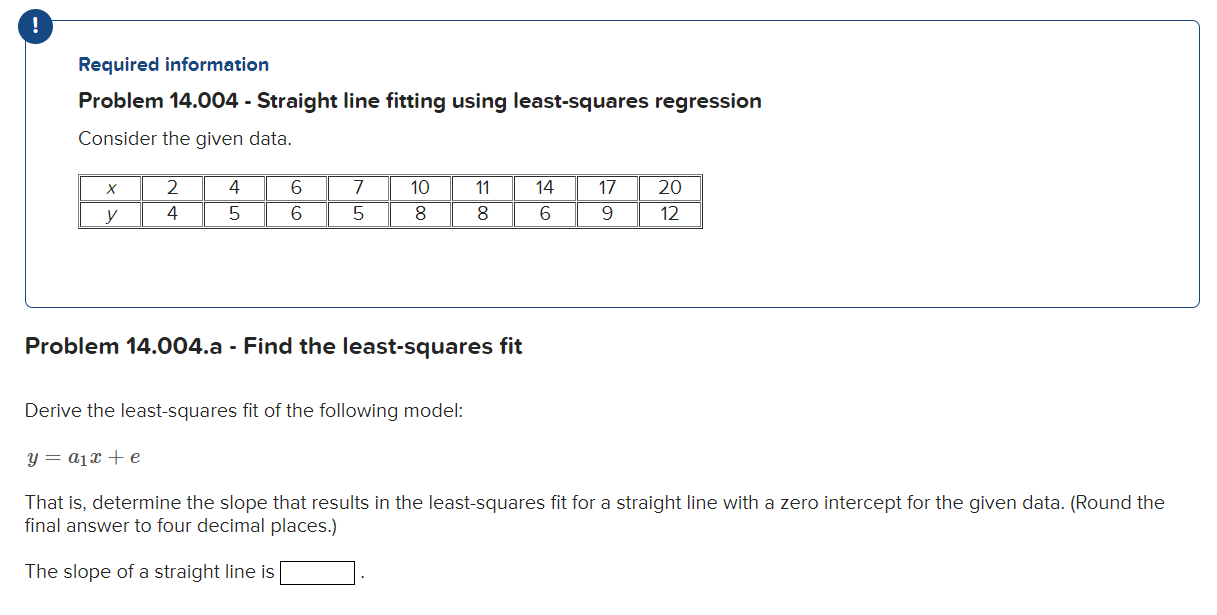

x = [2, 4, 6, 7, 10, 11, 14, 17, 20];
y = [4, 5, 6, 5, 8, 8, 6, 9, 12];
help linregr

  linregr: linear regression curve fitting
  [a, r2] = linregr(x,y): Least squares fit of straight
  line to data by solving the normal equations
  input:
  x = independent variable
  y = dependent variable
  output:
  a = vector of slope, a(1), and intercept, a(2)
  r2 = coefficient of determination



a1 = linregrzero(x,y)

a1 = 0.6144

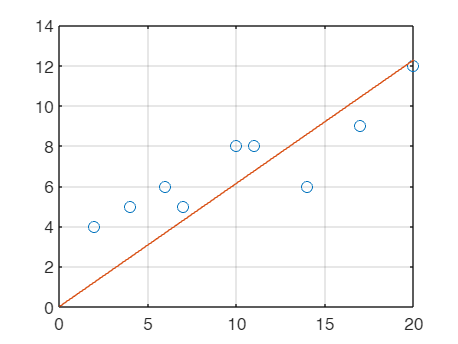

hold off;

coefficients = polyfit(x, y, 1) % used for slopes and intercepts, built-in

coefficients =     0.3678    3.2807


## Prob 4

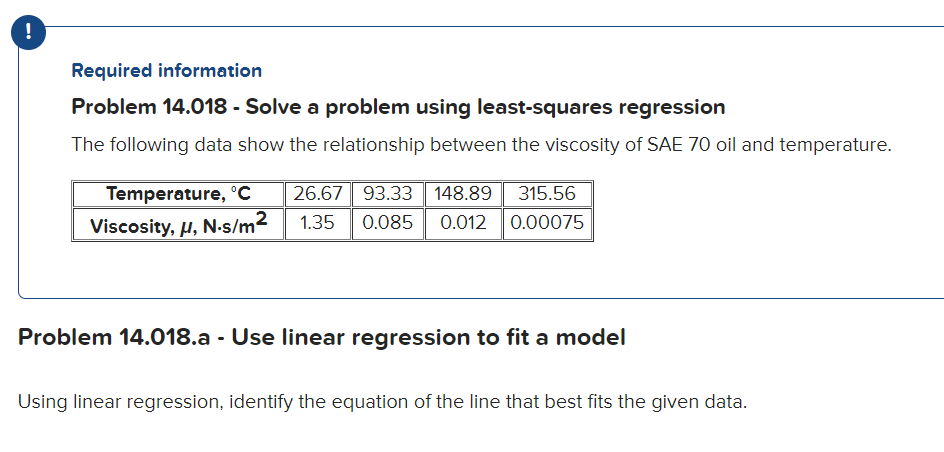

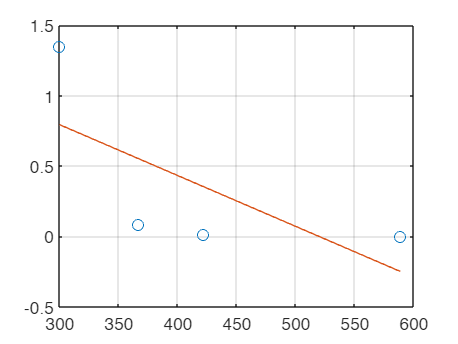

a =    -0.0036    1.8780


r2 = 0.4586

T = [26.67 93.33 148.89 315.56];
T = T + 273;
mu = [1.35 0.085 0.012 0.00075];
figure;
[a, r2] = linregr(T,mu) % clearly doesn't look right

coefficients = polyfit(T, mu, 1) 

coefficients =    -0.0036    1.8780


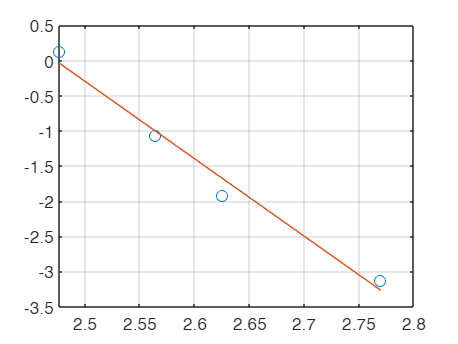

a_t =   -11.0192   27.2512


r2_t = 0.9798


% we need to get to form
%     a0*T^b
% transformation: 
%     log mu = log a2 + b2 log T
[a_t, r2_t] = linregr(log10(T),log10(mu))

a0 = 10^(a_t(2))

a0 = 1.7830e+27

b = (a_t(1))

b = -11.0192


% I think they're wrong....

We regress log10*µ* versus log10*T* to give

log10*µ* = 4.581471 – 3.01338log10*T*

Therefore, *α*2 = 104.581471 = 38,147.94 and *β*2 = –3.01338, and the power model is *µ* = 38,147.94*T*–3.01338.

r2 = 0.9757

## Prob 5 - nonlinear

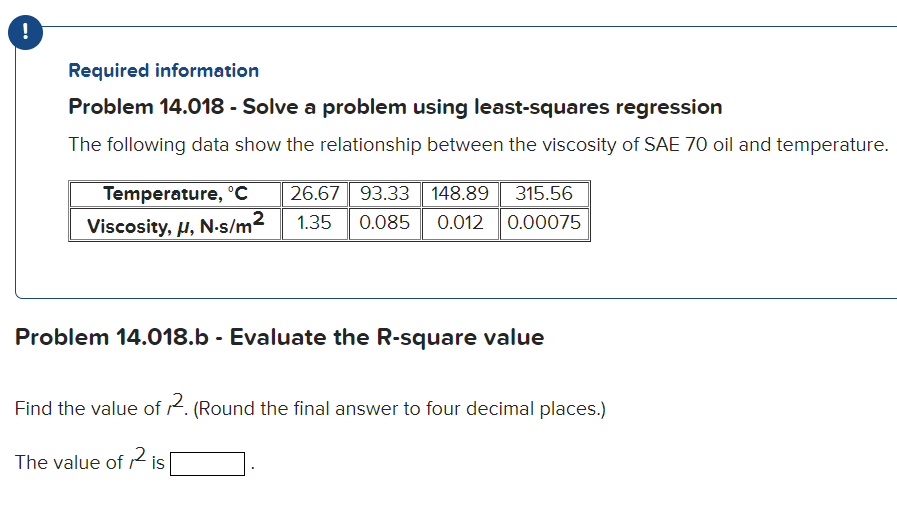

## Prob 6

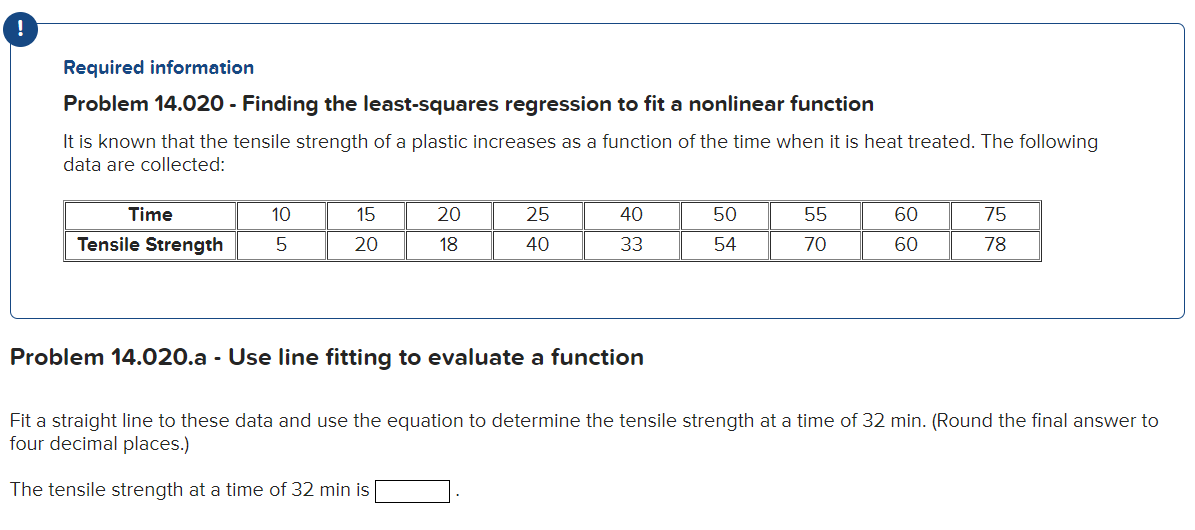

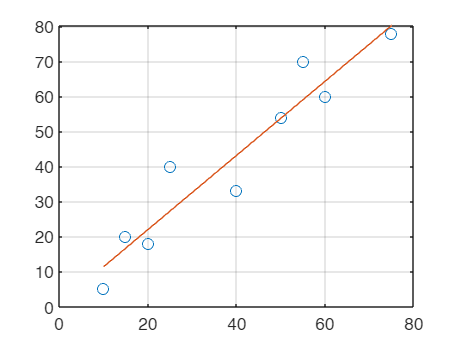

a_TT =     1.0590    0.8179


r2_TT = 0.9058

 Time = [10, 15, 20, 25, 40, 50, 55, 60, 75];
 TensStr = [5, 20, 18, 40, 33, 54, 70, 60, 78];

 [a_TT, r2_TT] = linregr(Time,TensStr)

 y_TensStr = polyval(a_TT,32)

y_TensStr = 34.7049

## Prob 7

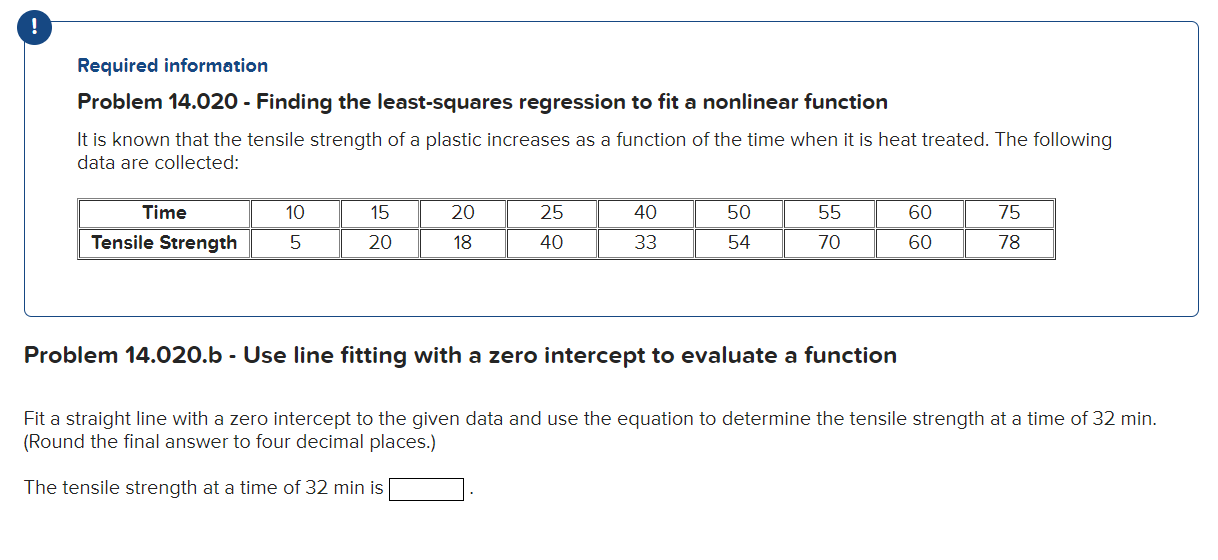

% Matlab only, Chat
 b = regress(TensStr', Time');   % no intercept term
y_TensStr_z = b * 32

y_TensStr_z = 34.4045


% Solve w/ least squares
a = (Time * TensStr') / (Time * Time');  % slope only
y_TensStr_zls = a * 32                 % tensile strength at 32 min

y_TensStr_zls = 34.4045

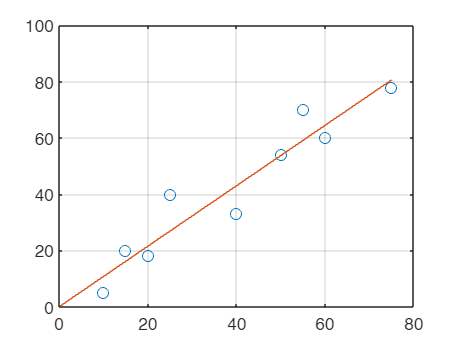


%% Actual method to use: 
a1 = linregrzero(Time, TensStr);